# **Discriminating voiced and unvoiced signals in speech.**

`Analyse a speech signal considering its short- time energy, short -time magnitude and zero crossing rate`


$$Ans:$$


clear all; clc;
[y1, Fs1] = audioread("arctic_a0001.wav")

y1 =    -0.0002   -0.3355
   -0.0001   -0.3354
    0.0002   -0.3313
    0.0003   -0.3293
    0.0002   -0.3288
    0.0001   -0.3268
    0.0001   -0.3253
    0.0002   -0.3245
    0.0001   -0.3229
    0.0001   -0.3205


Fs1 = 32000

sp = y1(:,1); % Where 1st coloumn has the speech information
egg = y1(:,2);% Where 2nd coloumn has the egg information

Fs = 16000;
m=resample(sp,Fs,Fs1) % which resamples the speech sp to 1600/3200

m =    -0.0002
    0.0002
    0.0002
    0.0001
    0.0002
   -0.0000
   -0.0001
   -0.0001
   -0.0000
    0.0000



t = 0:1/Fs :(length(m)-1)/Fs;
% Objective = size(t)
Framesize = 0.02*Fs;
Shift = 0.01*Fs;

seg = buffer(m,Framesize,Shift)

seg =          0   -0.0002   -0.0003    0.0003    0.0003    0.0001    0.0001    0.0001   -0.0002   -0.0002    0.0003   -0.0001   -0.0001   -0.0004    0.0000    0.0003    0.0001   -0.0004   -0.0003   -0.0001    0.0000   -0.0006   -0.0009   -0.0370   -0.0293   -0.0710   -0.1317   -0.1086    0.1923   -0.2007    0.2903    0.0754    0.0775   -0.3796    0.0518   -0.0734    0.1237    0.0064   -0.0219   -0.0065    0.0031    0.0010   -0.0014    0.0013    0.0009   -0.0082   -0.0045    0.0850   -0.3178   -0.0434
         0    0.0002   -0.0003    0.0003    0.0002    0.0004    0.0000    0.0001   -0.0001    0.0001    0.0003   -0.0000   -0.0001    0.0001    0.0001    0.0003    0.0001   -0.0000   -0.0003   -0.0001    0.0001   -0.0002   -0.0010   -0.0801   -0.0197   -0.0560   -0.1777   -0.0825    0.1189   -0.2092    0.4053    0.0088    0.0419   -0.3107   -0.0549   -0.0977    0.2046    0.0081   -0.0176    0.0023    0.0026   -0.0021   -0.0030   -0.0010    0.0005    0.0097    0.0055    0.0633   -0.3399   


[len,block] = size(seg);

m_wind = seg;

## `Short Time Energy`

st_E = sum(m_wind.^2,1);
st_E = st_E / max(st_E)

st_E =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0176    0.2018    0.4796    0.6431    0.7371    0.6593    0.7751    0.9492    0.9375    1.0000    0.9182    0.6742    0.6287    0.4696    0.1451    0.0385    0.0026    0.0003    0.0001    0.0000    0.0001    0.0004    0.0017    0.0412    0.1536    0.2870    0.3078    0.2193



t_s = 1/Fs:0.01:(length(st_E)*0.01);

subplot(2,2,1); 
plot(t,m);hold on;
plot(t_s,st_E,'G'); legend('speech signal','short-time energy');

## `Short Time Magnitude`

st_M = sum(abs(m_wind),1);
st_M = st_M / max(st_M)

st_M =     0.0006    0.0012    0.0016    0.0017    0.0010    0.0008    0.0007    0.0008    0.0009    0.0008    0.0007    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0019    0.0025    0.0236    0.0907    0.3625    0.6587    0.7800    0.8542    0.7976    0.8593    0.9693    0.9700    1.0000    0.9523    0.7820    0.7462    0.6351    0.3527    0.1668    0.0417    0.0146    0.0071    0.0061    0.0081    0.0133    0.0337    0.1494    0.3473    0.5019    0.5232    0.4398



subplot(2,2,2);
plot(t,m);hold on;
plot(t_s,st_M,'G'); legend('speech signal','short-time magnitude');

## `Short time Zero Crossing Rate`

st_ZCR = sum(abs(sign(m_wind(1:end-1,:))-sign(m_wind(2:end,:))),1)/2/len;
st_ZCR = st_ZCR/max(st_ZCR)

st_ZCR =     0.0545    0.0639    0.0263    0.0602    0.1504    0.2105    0.1917    0.1353    0.1391    0.1466    0.1466    0.1429    0.1316    0.1090    0.1353    0.1842    0.1316    0.0940    0.1391    0.0902    0.0188    0.0752    0.1203    0.1053    0.0865    0.0902    0.0940    0.0977    0.0977    0.0940    0.0977    0.1090    0.1128    0.1203    0.1203    0.0865    0.0489    0.0902    0.3421    0.5113    0.6241    0.7782    0.8233    0.8120    0.5940    0.2368    0.0752    0.0865    0.0827    0.0752


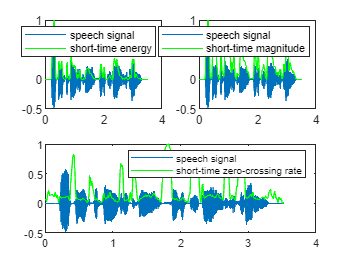


subplot(2,2,[3,4]);
%figure(); 
plot(t,m);hold on;
plot(t_s,st_ZCR,'G'); legend('speech signal','short-time zero-crossing rate');

`Part 2:`

`Consider a speech signal sampled at 8 kHz with 16 bits/sample as bit resolution. Write a Matlab program to compute the short-time energy and zero-crossing rate using a rectangular window of frame lengths N = 40, 80, 160 and 320 samples. Plot the resulting short-time estimates on a common plot. What effects do you see as the window length shortens or lengthens? Note: Assume, frame shift = frame length/2.`


$$Ans:$$


clear all; clc;
[y1, Fs1] = audioread("Male_voice.wav")

y1 =    -0.0000   -0.2092
    0.0002   -0.3562
    0.0001   -0.3087
   -0.0001   -0.3265
   -0.0000   -0.3072
   -0.0001   -0.3119
   -0.0001   -0.3016
   -0.0001   -0.3020
   -0.0001   -0.2970
   -0.0001   -0.2947


Fs1 = 8000

info = audioinfo('Male_voice.wav')

info = struct with fields:
             Filename: 'C:\Users\phvpa\OneDrive - Amrita Vishwa Vidyapeetham\Semister-3 Classes\Speech Processing\Experiments\Male_voice.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 8000
         TotalSamples: 28240
             Duration: 3.5300
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


sp = y1(:,1);  % Where 1st coloumn has the speech information
Fs = 8000;

m=sp%resample(sp,Fs,Fs1) % which resamples the speech sp to 1600/3200

m =    -0.0000
    0.0002
    0.0001
   -0.0001
   -0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0001
   -0.0001



t = 0:1/Fs1 :(length(m)-1)/Fs1;
All_Frames = [40 80 160 320];

## `Short Time Energy`

seg1 = buffer(m,All_Frames(1),All_Frames(1)/2)

seg1 =          0   -0.0000    0.0001    0.0004    0.0002   -0.0003   -0.0002    0.0002    0.0001    0.0003    0.0005    0.0005    0.0002    0.0002    0.0003         0    0.0001    0.0002    0.0001   -0.0002    0.0001    0.0000   -0.0000    0.0002    0.0003    0.0001   -0.0001    0.0002   -0.0000   -0.0002    0.0002    0.0001   -0.0003   -0.0001    0.0002   -0.0001    0.0001    0.0003   -0.0001   -0.0001    0.0002   -0.0001   -0.0001    0.0002    0.0001   -0.0001         0    0.0002   -0.0002   -0.0002
         0    0.0002    0.0001    0.0004    0.0002   -0.0002   -0.0001    0.0002    0.0002    0.0003    0.0005    0.0004    0.0001    0.0003    0.0004    0.0000    0.0002    0.0004    0.0001   -0.0001    0.0000    0.0000         0    0.0002    0.0003    0.0000   -0.0001    0.0002   -0.0000   -0.0001    0.0002    0.0001   -0.0003    0.0001    0.0002   -0.0001    0.0001    0.0003   -0.0001   -0.0001    0.0002   -0.0000   -0.0001    0.0002    0.0002   -0.0001         0    0.0002   -0.0002  


m_wind1 = seg1;
st_E1 = sum(m_wind1.^2,1);st_E1 = st_E1 / max(st_E1)

st_E1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



t_s_1 = 1/Fs:0.0025:(length(st_E1)*0.0025);

%-----------------------------------------------------------------------%
seg2 = buffer(m,All_Frames(2),All_Frames(2)/2)

seg2 =          0   -0.0000    0.0004   -0.0003    0.0002    0.0003    0.0005    0.0002         0    0.0002   -0.0002    0.0000    0.0002    0.0001    0.0002   -0.0002    0.0001   -0.0001   -0.0001    0.0003   -0.0001   -0.0001    0.0002   -0.0001    0.0002   -0.0002         0    0.0001   -0.0002    0.0002   -0.0001    0.0001         0   -0.0002    0.0001   -0.0003    0.0001   -0.0001   -0.0002    0.0001   -0.0001   -0.0005    0.0005   -0.0010    0.0006   -0.0376   -0.0143   -0.0311   -0.1703   -0.0713
         0    0.0002    0.0004   -0.0002    0.0002    0.0003    0.0004    0.0003    0.0000    0.0004   -0.0001    0.0000    0.0002    0.0000    0.0002   -0.0001    0.0001    0.0001   -0.0001    0.0003   -0.0001   -0.0000    0.0002   -0.0001    0.0002   -0.0000    0.0000    0.0001   -0.0002    0.0003   -0.0001   -0.0000   -0.0000   -0.0001    0.0001   -0.0002    0.0002         0   -0.0002    0.0001   -0.0002   -0.0003    0.0005   -0.0009    0.0006   -0.1226    0.0042   -0.0173    0.0078  


[~,block2] = size(seg2);

m_wind2 = seg2;
st_E2 = sum(m_wind2.^2,1);st_E2 = st_E2 / max(st_E2)

st_E2 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0095    0.0259    0.0198    0.1994    0.3208    0.3780    0.4898



t_s_2 = 1/Fs:0.005:(length(st_E2)*0.005);
%-----------------------------------------------------------------------%
seg3 = buffer(m,All_Frames(3),All_Frames(3)/2)

seg3 =          0   -0.0000   -0.0003    0.0003    0.0002    0.0002    0.0000    0.0001   -0.0002   -0.0001    0.0003   -0.0001   -0.0001   -0.0002    0.0001    0.0002    0.0001   -0.0002   -0.0003   -0.0001    0.0001   -0.0005   -0.0010   -0.0376   -0.0311   -0.0713   -0.1244   -0.1096    0.1908   -0.2026    0.2948    0.0750    0.0738   -0.3770    0.0494   -0.0732    0.1237    0.0056   -0.0229   -0.0008    0.0026   -0.0006   -0.0013   -0.0008    0.0011   -0.0005    0.0004    0.0825   -0.3231   -0.0438
         0    0.0002   -0.0002    0.0003    0.0003    0.0004    0.0000    0.0000   -0.0001    0.0001    0.0003   -0.0000   -0.0001   -0.0000    0.0001    0.0003   -0.0000   -0.0001   -0.0002         0    0.0001   -0.0003   -0.0009   -0.1226   -0.0173   -0.0401   -0.2028   -0.0328    0.0564   -0.2243    0.4064   -0.0855    0.0342   -0.2720   -0.1151   -0.1156    0.2658    0.0096   -0.0033    0.0002    0.0020    0.0002   -0.0009    0.0024    0.0016    0.0027    0.0048    0.0351   -0.3040  



m_wind3 = seg3;
st_E3 = sum(m_wind3.^2,1);st_E3 = st_E3 / max(st_E3)

st_E3 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0174    0.2028    0.4825    0.6465    0.7396    0.6622    0.7799    0.9556    0.9440    1.0000    0.9237    0.6842    0.6327    0.4726    0.1461    0.0386    0.0025    0.0002    0.0000    0.0000    0.0000    0.0002    0.0012    0.0408    0.1512    0.2892    0.3134    0.2207



t_s_3 = 1/Fs:0.01:(length(st_E3)*0.01);
%-----------------------------------------------------------------------%
seg4 = buffer(m,All_Frames(4),All_Frames(4)/2)

seg4 =          0   -0.0000    0.0003    0.0002    0.0001   -0.0001   -0.0001   -0.0002    0.0002   -0.0002   -0.0001   -0.0005   -0.0376   -0.0713   -0.1096   -0.2026    0.0750   -0.3770   -0.0732    0.0056   -0.0008   -0.0006   -0.0008   -0.0005    0.0825   -0.0438   -0.1048    0.1650   -0.1118    0.0869    0.1377    0.0050    0.0172   -0.0149    0.0011    0.0005   -0.0012    0.0023    0.0544    0.0589    0.0134    0.0075    0.0045    0.0160   -0.0044   -0.0039    0.1190   -0.0468    0.1208    0.0372
         0    0.0002    0.0003    0.0004    0.0000    0.0001   -0.0000   -0.0000    0.0003   -0.0001         0   -0.0003   -0.1226   -0.0401   -0.0328   -0.2243   -0.0855   -0.2720   -0.1156    0.0096    0.0002    0.0002    0.0024    0.0027    0.0351   -0.0480   -0.1357    0.1392   -0.1187    0.1288    0.1210    0.0137    0.0295   -0.0141   -0.0009    0.0001   -0.0013    0.0034    0.0463    0.0306    0.0150    0.0145    0.0031    0.0171   -0.0163    0.0117    0.1003   -0.0855    0.0948  


m_wind4 = seg4;
st_E4 = sum(m_wind4.^2,1);st_E4 = st_E4 / max(st_E4)

st_E4 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0029    0.1066    0.4343    0.6692    0.8273    1.0000    0.8612    0.5916    0.2614    0.0198    0.0001    0.0001    0.0210    0.1688    0.2607    0.1973    0.1783    0.2170    0.2776    0.2447    0.1163    0.0338    0.0088    0.0010    0.0000    0.0001    0.0228    0.1676    0.2081    0.0742    0.0158    0.0071    0.0042    0.0512    0.2661    0.3695    0.2703    0.2429    0.2494    0.2312


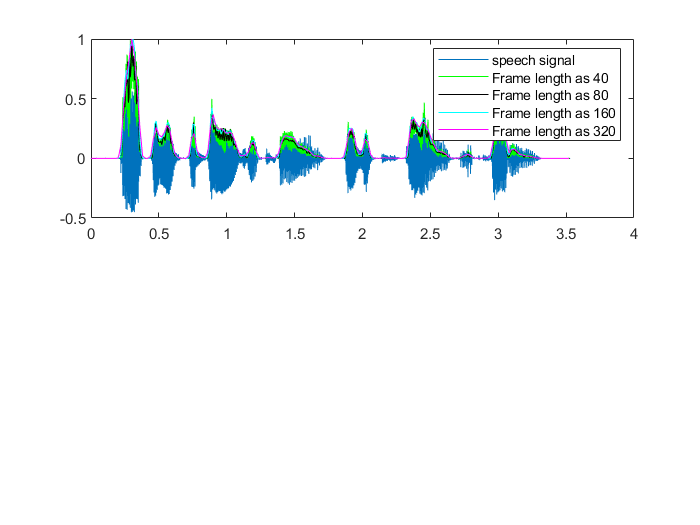

t_s_4 = 1/Fs:0.02:(length(st_E4)*0.02);
%-----------------------------------------------------------------------%

subplot(2,1,1);
plot(t,m);hold on;
plot(t_s_1,st_E1,'G'); hold on;%legend('speech signal','Frame length as 40');
plot(t_s_2,st_E2,'Color', 'k'); hold on;%legend('speech signal','Frame length as 80');
plot(t_s_3,st_E3,'Color', 'c'); hold on; 
plot(t_s_4,st_E4,'m'); legend('speech signal','Frame length as 40','Frame length as 80','Frame length as 160','Frame length as 320')

seg1 = buffer(m,All_Frames(1),All_Frames(1)/2)

seg1 =          0   -0.0000    0.0001    0.0004    0.0002   -0.0003   -0.0002    0.0002    0.0001    0.0003    0.0005    0.0005    0.0002    0.0002    0.0003         0    0.0001    0.0002    0.0001   -0.0002    0.0001    0.0000   -0.0000    0.0002    0.0003    0.0001   -0.0001    0.0002   -0.0000   -0.0002    0.0002    0.0001   -0.0003   -0.0001    0.0002   -0.0001    0.0001    0.0003   -0.0001   -0.0001    0.0002   -0.0001   -0.0001    0.0002    0.0001   -0.0001         0    0.0002   -0.0002   -0.0002
         0    0.0002    0.0001    0.0004    0.0002   -0.0002   -0.0001    0.0002    0.0002    0.0003    0.0005    0.0004    0.0001    0.0003    0.0004    0.0000    0.0002    0.0004    0.0001   -0.0001    0.0000    0.0000         0    0.0002    0.0003    0.0000   -0.0001    0.0002   -0.0000   -0.0001    0.0002    0.0001   -0.0003    0.0001    0.0002   -0.0001    0.0001    0.0003   -0.0001   -0.0001    0.0002   -0.0000   -0.0001    0.0002    0.0002   -0.0001         0    0.0002   -0.0002  


[len1,block1] = size(seg1);

m_wind1 = seg1;
%st_E1 = sum(m_wind1.^2,1);st_E1 = st_E1 / max(st_E1)
st_ZCR1 = sum(abs(sign(m_wind1(1:end-1,:))-sign(m_wind1(2:end,:))),1)/2/len1;
st_ZCR1 = st_ZCR1/max(st_ZCR1)

st_ZCR1 =     0.1447    0.1316         0    0.0526    0.0526    0.0526    0.0526         0         0         0    0.0263    0.0263         0    0.0526    0.1579    0.0921         0    0.0526    0.1842    0.2632    0.2632    0.2368    0.1053    0.0263    0.0789    0.1053    0.1184    0.1316    0.1316    0.0789    0.0789    0.0921    0.1316    0.1579    0.1579    0.1053    0.0526    0.0526    0.0526    0.0526    0.0526    0.0526    0.0263    0.0789    0.1316    0.1053    0.0921    0.0526    0.0526    0.0526



t_s_1 = 1/Fs:0.0025:(length(st_ZCR1)*0.0025);

%-----------------------------------------------------------------------%
seg2 = buffer(m,All_Frames(2),All_Frames(2)/2)

seg2 =          0   -0.0000    0.0004   -0.0003    0.0002    0.0003    0.0005    0.0002         0    0.0002   -0.0002    0.0000    0.0002    0.0001    0.0002   -0.0002    0.0001   -0.0001   -0.0001    0.0003   -0.0001   -0.0001    0.0002   -0.0001    0.0002   -0.0002         0    0.0001   -0.0002    0.0002   -0.0001    0.0001         0   -0.0002    0.0001   -0.0003    0.0001   -0.0001   -0.0002    0.0001   -0.0001   -0.0005    0.0005   -0.0010    0.0006   -0.0376   -0.0143   -0.0311   -0.1703   -0.0713
         0    0.0002    0.0004   -0.0002    0.0002    0.0003    0.0004    0.0003    0.0000    0.0004   -0.0001    0.0000    0.0002    0.0000    0.0002   -0.0001    0.0001    0.0001   -0.0001    0.0003   -0.0001   -0.0000    0.0002   -0.0001    0.0002   -0.0000    0.0000    0.0001   -0.0002    0.0003   -0.0001   -0.0000   -0.0000   -0.0001    0.0001   -0.0002    0.0002         0   -0.0002    0.0001   -0.0002   -0.0003    0.0005   -0.0009    0.0006   -0.1226    0.0042   -0.0173    0.0078  


[len2,block2] = size(seg2);

m_wind2 = seg2;
st_ZCR2 = sum(abs(sign(m_wind2(1:end-1,:))-sign(m_wind2(2:end,:))),1)/2/len2;
st_ZCR2 = st_ZCR2/max(st_ZCR2)

st_ZCR2 =     0.0753    0.0959    0.0548    0.0274         0    0.0137    0.0411    0.0822    0.0753    0.1644    0.2603    0.1370    0.0685    0.1233    0.1096    0.0890    0.1370    0.1370    0.0822    0.0548    0.0685    0.0685    0.0959    0.0822    0.0548    0.1096    0.1164    0.0548    0.0548    0.0548    0.0274    0.1096    0.1164    0.0685    0.0685    0.0685    0.1918    0.1507    0.0274    0.0137    0.0137    0.0274    0.0548    0.1644    0.2466    0.2192    0.1918    0.1644    0.1507    0.1507



t_s_2 = 1/Fs:0.005:(length(st_ZCR2)*0.005);
%-----------------------------------------------------------------------%
seg3 = buffer(m,All_Frames(3),All_Frames(3)/2)

seg3 =          0   -0.0000   -0.0003    0.0003    0.0002    0.0002    0.0000    0.0001   -0.0002   -0.0001    0.0003   -0.0001   -0.0001   -0.0002    0.0001    0.0002    0.0001   -0.0002   -0.0003   -0.0001    0.0001   -0.0005   -0.0010   -0.0376   -0.0311   -0.0713   -0.1244   -0.1096    0.1908   -0.2026    0.2948    0.0750    0.0738   -0.3770    0.0494   -0.0732    0.1237    0.0056   -0.0229   -0.0008    0.0026   -0.0006   -0.0013   -0.0008    0.0011   -0.0005    0.0004    0.0825   -0.3231   -0.0438
         0    0.0002   -0.0002    0.0003    0.0003    0.0004    0.0000    0.0000   -0.0001    0.0001    0.0003   -0.0000   -0.0001   -0.0000    0.0001    0.0003   -0.0000   -0.0001   -0.0002         0    0.0001   -0.0003   -0.0009   -0.1226   -0.0173   -0.0401   -0.2028   -0.0328    0.0564   -0.2243    0.4064   -0.0855    0.0342   -0.2720   -0.1151   -0.1156    0.2658    0.0096   -0.0033    0.0002    0.0020    0.0002   -0.0009    0.0024    0.0016    0.0027    0.0048    0.0351   -0.3040  


[len3,block3] = size(seg3);

m_wind3 = seg3;
st_ZCR3 = sum(abs(sign(m_wind3(1:end-1,:))-sign(m_wind3(2:end,:))),1)/2/len3;
st_ZCR3 = st_ZCR3/max(st_ZCR3)

st_ZCR3 =     0.0524    0.0629    0.0210    0.0490    0.1259    0.1538    0.1329    0.1084    0.1189    0.0979    0.0699    0.0769    0.0979    0.0839    0.0559    0.0839    0.0909    0.0699    0.1189    0.0839    0.0210    0.0979    0.2028    0.1958    0.1608    0.1678    0.1748    0.1818    0.1818    0.1748    0.1818    0.1888    0.1958    0.2238    0.2168    0.1608    0.0909    0.0769    0.1329    0.2238    0.3776    0.4895    0.4056    0.3916    0.3357    0.1329    0.0909    0.1469    0.1538    0.1399



t_s_3 = 1/Fs:0.01:(length(st_ZCR3)*0.01);
%-----------------------------------------------------------------------%
seg4 = buffer(m,All_Frames(4),All_Frames(4)/2)

seg4 =          0   -0.0000    0.0003    0.0002    0.0001   -0.0001   -0.0001   -0.0002    0.0002   -0.0002   -0.0001   -0.0005   -0.0376   -0.0713   -0.1096   -0.2026    0.0750   -0.3770   -0.0732    0.0056   -0.0008   -0.0006   -0.0008   -0.0005    0.0825   -0.0438   -0.1048    0.1650   -0.1118    0.0869    0.1377    0.0050    0.0172   -0.0149    0.0011    0.0005   -0.0012    0.0023    0.0544    0.0589    0.0134    0.0075    0.0045    0.0160   -0.0044   -0.0039    0.1190   -0.0468    0.1208    0.0372
         0    0.0002    0.0003    0.0004    0.0000    0.0001   -0.0000   -0.0000    0.0003   -0.0001         0   -0.0003   -0.1226   -0.0401   -0.0328   -0.2243   -0.0855   -0.2720   -0.1156    0.0096    0.0002    0.0002    0.0024    0.0027    0.0351   -0.0480   -0.1357    0.1392   -0.1187    0.1288    0.1210    0.0137    0.0295   -0.0141   -0.0009    0.0001   -0.0013    0.0034    0.0463    0.0306    0.0150    0.0145    0.0031    0.0171   -0.0163    0.0117    0.1003   -0.0855    0.0948  


[len4,block4] = size(seg4);

m_wind4 = seg4;
st_ZCR4 = sum(abs(sign(m_wind4(1:end-1,:))-sign(m_wind4(2:end,:))),1)/2/len4;
st_ZCR4 = st_ZCR4/max(st_ZCR4)

st_ZCR4 =     0.0363    0.0611    0.1107    0.1431    0.1145    0.0992    0.0878    0.0916    0.0840    0.0878    0.0992    0.1641    0.1985    0.1908    0.1947    0.1985    0.2252    0.2099    0.1298    0.1641    0.3893    0.4847    0.2863    0.1527    0.1565    0.1412    0.1221    0.1374    0.1565    0.1412    0.0992    0.0496    0.0458    0.0916    0.1145    0.1221    0.1260    0.1145    0.1145    0.0916    0.0611    0.0458    0.0649    0.1145    0.1489    0.1450    0.1756    0.2328    0.2519    0.1870


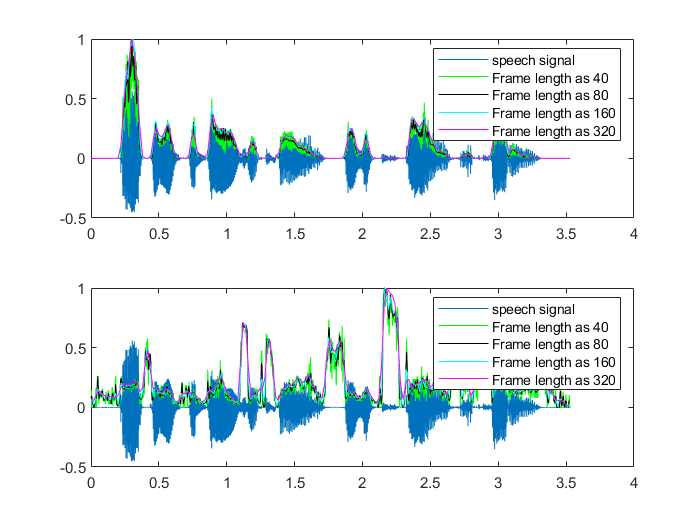


t_s_4 = 1/Fs:0.02:(length(st_ZCR4)*0.02);
%-----------------------------------------------------------------------%

subplot(2,1,2);
plot(t,m);hold on;
plot(t_s_1,st_ZCR1,'G'); hold on;%legend('speech signal','Frame length as 40');
plot(t_s_2,st_ZCR2,'Color', 'k'); hold on;%legend('speech signal','Frame length as 80');
plot(t_s_3,st_ZCR3,'Color', 'c'); hold on; 
plot(t_s_4,st_ZCR4,'m'); legend('speech signal','Frame length as 40','Frame length as 80','Frame length as 160','Frame length as 320')